### 4.1 Hands-on 3

"Please provide a solution and the corresponding explanation for 1.3."

Hands-on 3 excercise 1.3 dealt with the Fourier transform of a recorded signal. The sound of a piano playing a single note is loaded into Matlab. 

clear all; close all;

piano = 'piano.wav';
[h, Fs_h] = audioread(piano); % h is signal, Fs_h is sampling frequency
h=h(:,1);

We then plot the time signal from 0 to 1 seconds. 

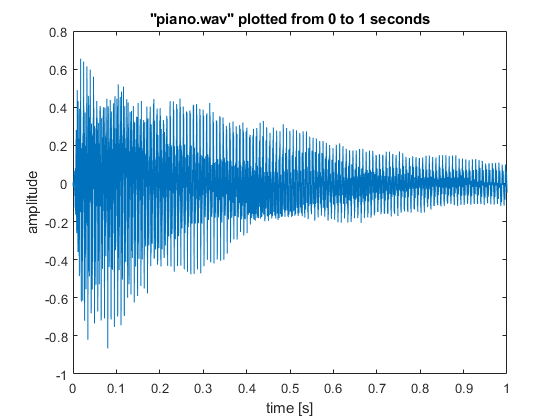

dt = 1/Fs_h; % sampling period
T = length(h)/Fs_h; % signal length
t = 0:dt:T-dt; % time vector

plot(t, h);
title('"piano.wav" plotted from 0 to 1 seconds')
xlim([0 1]); % plot the time signal from 0 to 1 seconds
xlabel('time [s]');
ylabel('amplitude');

figure

Thereafter, the spectrum of the whole signal plotted with Hz and dB on the x- and y-axis respectively.

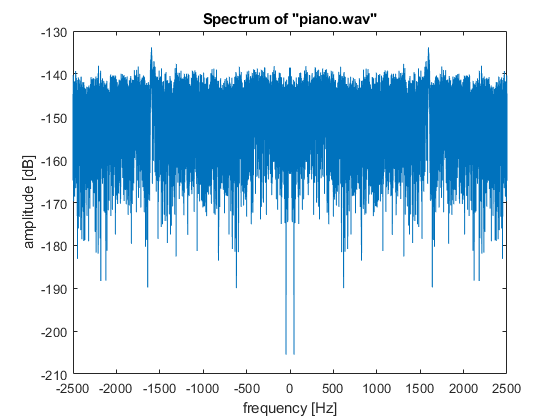

Y = fft(h); % computes Fourier transform of h, includes positive and negative frequencies
Y = Y/(length(Y)); % scaling
df = 1/T;
f = (-Fs_h/2):df:(Fs_h/2 - df); % frequency vector
YdB = mag2db(abs(Y));

plot(f,YdB);
title('Spectrum of "piano.wav"')
ax = gca;
ax.XLim = [-2500 2500];
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');

figure

***(The previous plot may be wrong since matlab returned the positive frequencies first! - the frequency vector for that plot should go from 0 to (fs/2 - fs/N) and then from -fs/2 to -fs/N!) - see intro_hands_on_03, the next f vector should however be correct. The next plot still uses the same fft, so be careful when changing the calculation of Y.***

To plot only the positive frequencies, including the DC component, we have to create new frequency and signal vectors, only containing values for the positive frequencies. MATLAB's fft-function returns the positive frequencies first, so the new vectors are created like this:

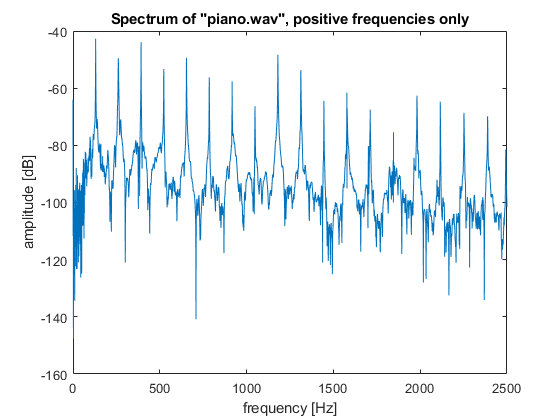

fpos = 0:df:(Fs_h/2 - df); % positive frequency vector
Ypos = Y(1:length(fpos)); % positive frequencies
YposdB = mag2db(abs(Ypos));

plot(fpos,YposdB);
title('Spectrum of "piano.wav", positive frequencies only')
ax = gca;
ax.XLim = [0 2500];
xlabel('frequency [Hz]');
ylabel('amplitude [dB]');

figure
% is this the power spectrum?

From the final plot, we can estimate the fundamental frequency of the signal by looking at the spectral peaks. The fundamental frequency is defined as the lowest frequency of a periodic waveform (wikipedia). We see that the lowest peak is found at 130.43 Hz and therefore, with a precision of 0.5 Hz, we estimate the fundamental frequency of the signal to be 130.5 Hz. 

The fundamental frequency is what we percieve as the musical pitch of a tone. 130.5 Hz roughly correlates with the fundamental of C3 on a piano, which sounds very similar to the tone played in 'piano.wav'. The other peaks in the spectrum represent the harmonics of the signal.

-------------------------------------------------

*(Now we have to transform a spectrum into the time domain via IFFT, because we want to synthesize the piano sound)*

*Generate spectrum, synthesize signal.*